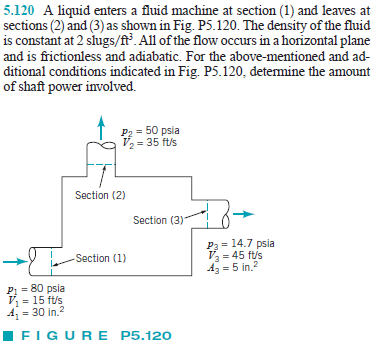

# constants

u = symunit;
rho = 2*u.slug/u.ft^3;

# inflow properties

% --------------------
% section 1
p1 = 80*u.psi;
V1 = 15*u.ft/u.s;
A1 = 30*u.in^2;
mdot1 = rho*rewrite(A1, 'US')*V1;
% --------------------

# outflow properties

% --------------------
% section 2
p2 = 50*u.psi;
V2 = 35*u.ft/u.s;
A2 = sym('A2');
mdot2(A2) = rewrite(rho*A2*V2, u.in);
% --------------------
% section 3
p3 = 14.7*u.psi;
V3 = 45*u.ft/u.s;
A3 = 5*u.in^2;
mdot3 = rho*rewrite(A3, 'US')*V3;
% --------------------

# conservation of mass

A2 = solve(mdot1 == mdot2+mdot3);
A2_vpa = vpa(A2, 3) %#ok

$$A2\_vpa = 6.43\,{\mathrm{in}}^{2}$$

clear A2_vpa;

# conservation of energy

Wdot = rewrite(-mdot1*(p1/rho+V1^2/2)+mdot2(A2)*(p2/rho+V2^2/2)+mdot3*(p3/rho+V3^2/2), u.HP_UK);
Wdot_vpa = vpa(Wdot, 4) %#ok

$$Wdot\_vpa = -31.03\,{\mathrm{HP}}_{\mathrm{UK}}$$

clear Wdot_vpa